% Data for two lines
x = linspace(0, 10, 100);
y1 = sin(x);
y2 = cos(x);

% Create a table to store the data, with duplicated 'x' for both lines
% x_combined = [x, x]';
% y_combined = [y1, y2]';Í
x_combined = (x)';
y_combined = (y1)';
% line_labels = [repmat({'sin(x)'}, 100, 1); repmat({'cos(x)'}, 100, 1)];
line_labels=[repmat({'sin(x)'}, 100, 1);]

line_labels = 100×1 cell array
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}
    {'sin(x)'}


data = table(x_combined, y_combined, line_labels, 'VariableNames', {'x', 'y', 'line'});

A = 1

A = 1

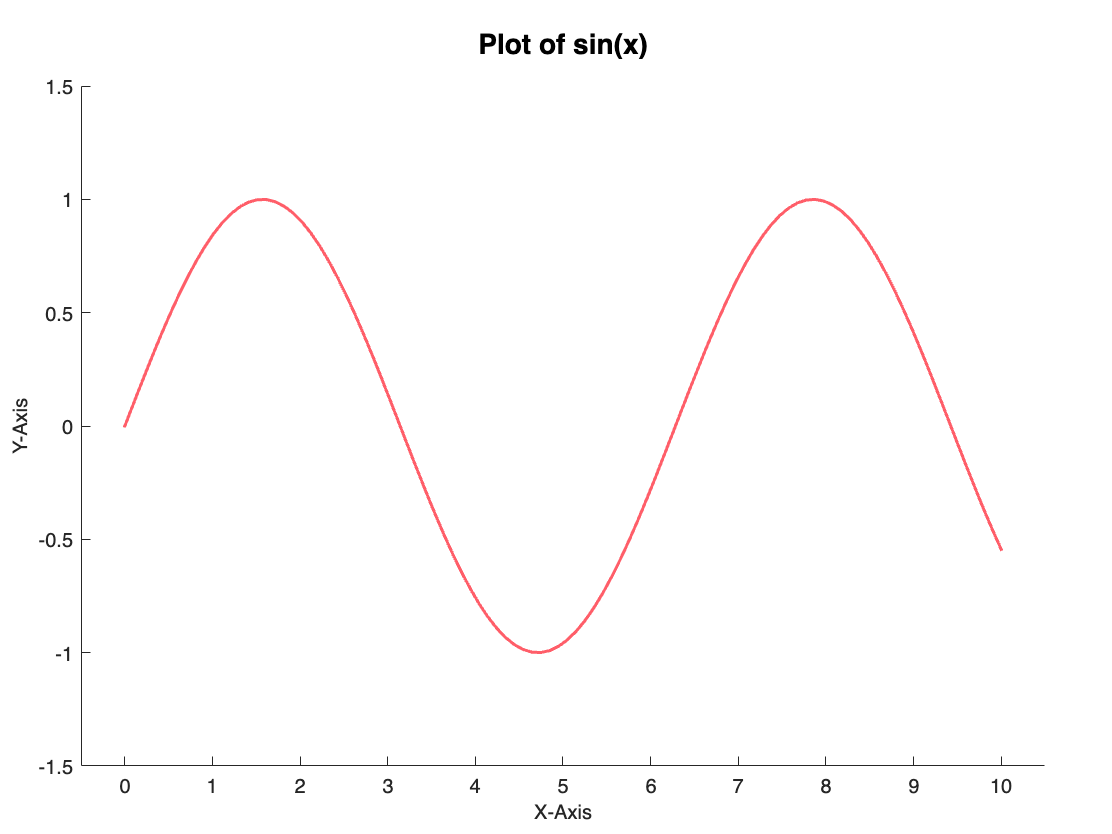

% Initialize gramm object
g = gramm('x', data.x, 'y', A*data.y, 'color', data.line);

% Set plot type to line
g.geom_line();

% Set y-axis limits
g.axe_property('YLim', [-1.5 1.5]);

% Set title and axis labels
g.set_title('Plot of sin(x)');
g.set_names('x', 'X-Axis', 'y', 'Y-Axis', 'color', 'Function');

% Draw the plot
figure('Position', [100 100 800 600]);
g.draw();

% g.export('file_name','my_figure','export_path','./','file_type','pdf')
g.export_d3('file_name','my_d3','x', 'X-Axis', 'y', 'Y-Axis','title','Plot of sin(x)');

D3.js code successfully written to my_d3.js
HTML file successfully written to my_d3.html
